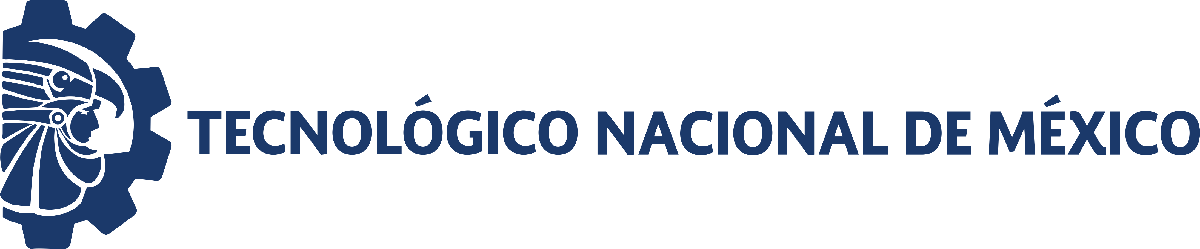                                 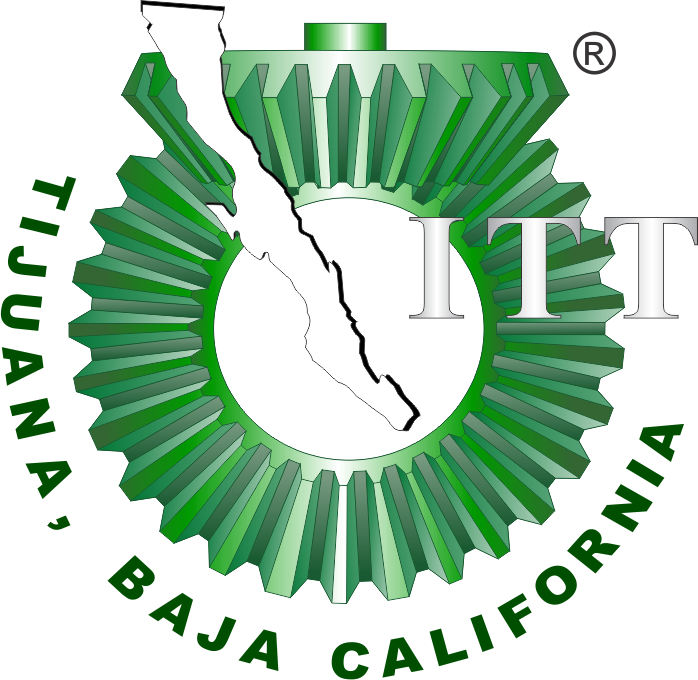

# Práctica 3: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

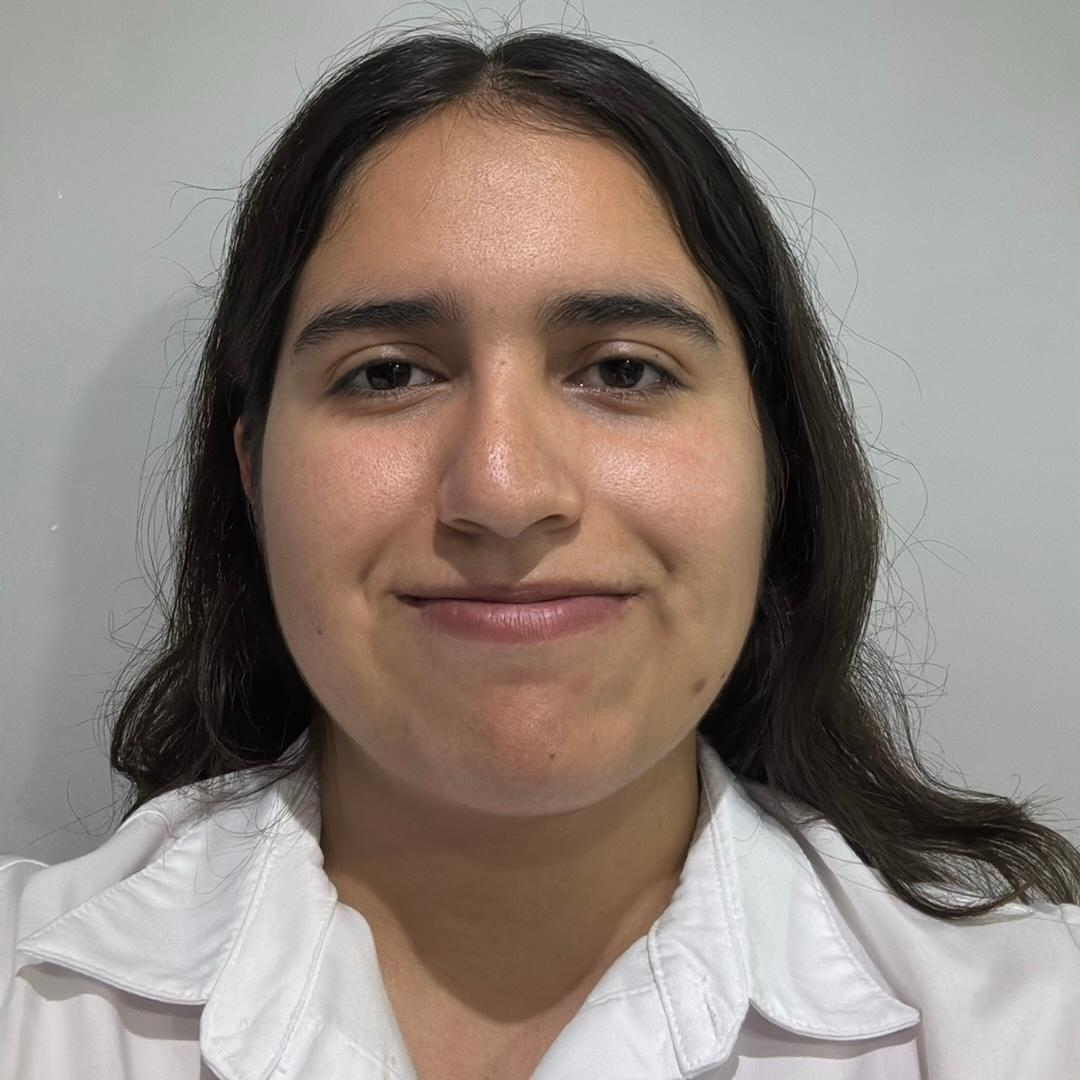

Nombre del alumno: **Anadalí Sifuentes Castro**

Número de control: **22212273**

Correo institucional: **L22212273@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistema3';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param('sistema3/Pa(t)','Minimum','-0.2');
set_param('sistema3/Pa(t)','Maximum','1');
set_param('sistema3/Pa(t)','Seed','106');
set_param('sistema3/Pa(t)','SampleTime','0.5');
x = sim(file,parameters);
writematrix(x.Ppa,'signal.xlsx')

## Respuesta en lazo abierto

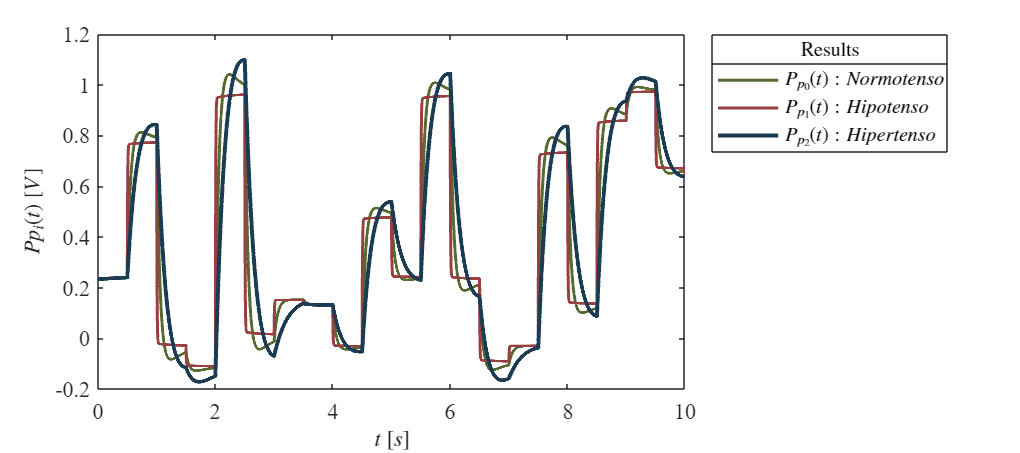

Signal = 'lazo_abierto';
x = sim(file,parameters);
plotsignalsa(x.t,x.Pp0,x.Pp1,x.Pp2,Signal)

## Respuesta en lazo cerrado

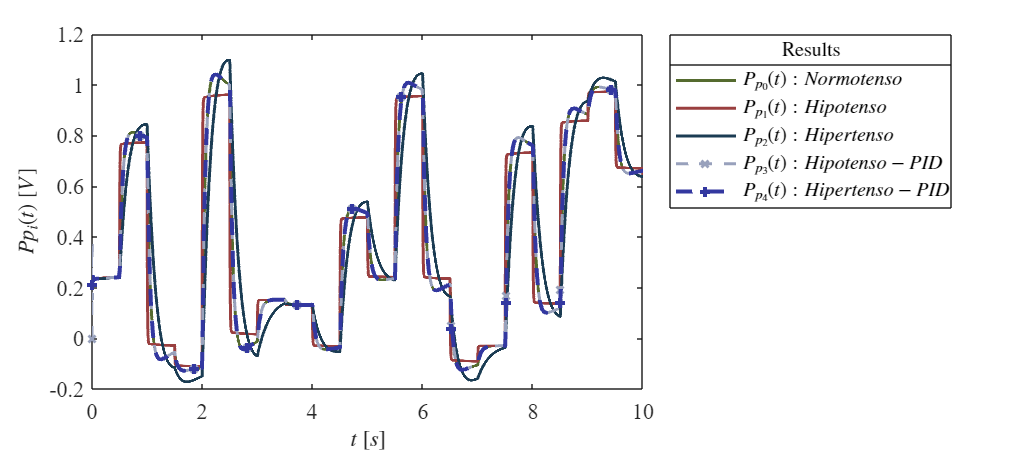

Signal = 'lazo_cerrado';
x = sim(file,parameters);
plotsignalsc(x.t,x.Pp0,x.Pp1,x.Pp2,x.Pp3,x.Pp4,Signal)

## Función: Respuesta a las señales

function plotsignalsc(t,Pp0,Pp1,Pp2,Pp3,Pp4,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [85,107,47;
                154,63,63;
                27,60,83;
                152,161,188;
                51,56,160;
                249,122,0]/255;
    colororder(mycolors)
    
    
    p = plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-',t,Pp3,'--x',t,Pp4,'--+',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(5),'LineWidth',2);
    L = legend('$P_{p_0}(t):Normotenso$','$P_{p_1}(t):Hipotenso$','$P_{p_2}(t):Hipertenso$','$P_{p_3}(t):Hipotenso-PID$','$P_{p_4}(t):Hipertenso-PID$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','on');
    title(L,['Results'],'FontSize',10);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','Vector')
end

function plotsignalsa(t,Pp0,Pp1,Pp2,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [85,107,47;
                154,63,63;
                27,60,83;
                152,161,188;
                51,56,160;
                249,122,0]/255;
    colororder(mycolors)
    
    
    p = plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3),'LineWidth',2);
    L = legend('$P_{p_0}(t):Normotenso$','$P_{p_1}(t):Hipotenso$','$P_{p_2}(t):Hipertenso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','on');
    title(L,['Results'],'FontSize',10);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','Vector')
end